Santeri Saariokari 253345, Luukas Kuusela 253061

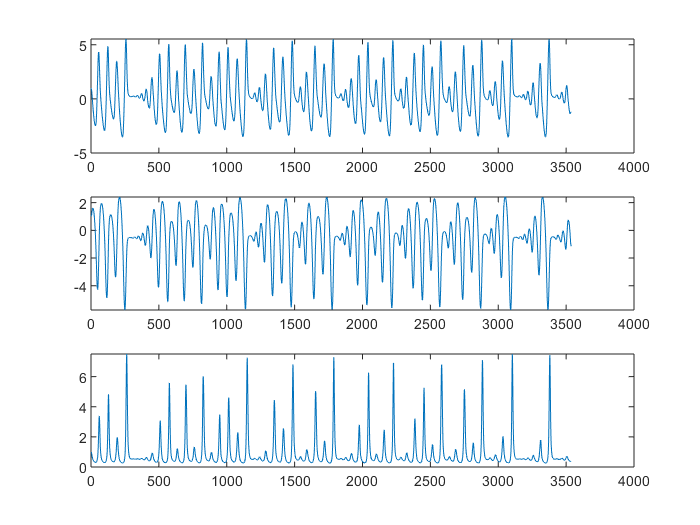

syms y(t);

a = 0.432;
b = 2;
c = 4;

ff = @(t, y) [-y(2)-y(3); y(1)+a*y(2); b+y(3)*(y(1)-c)];

[t, y] = ode45(ff, [0 400], [1;1;1]);

plot3(y(:,1), y(:,2), y(:,3))

subplot(3,1,1);
plot(y(:,1))

subplot(3,1,2);
plot(y(:,2))

subplot(3,1,3);
plot(y(:,3))